clc;clear;close all;

## 读取点

warning off
[num,txt,raw] = xlsread("方涵复测_2025_03_26.xlsx");

shendu = 0.2;
phi = deg2rad(62.2);
shenglunum = 8;
a = shendu*ones(1,2*shenglunum);
distanceThreshold = 0.2;



PAB = [0.655; -0.943; -0.478 ];
P_bound1 = num([72,74,73],2);
P_bound2 = num([72,74,73],3);

xl = num(27,~isnan(num(27,:)));
yl = num(29,~isnan(num(29,:)));
zl = num(28,~isnan(num(28,:)));
side_faces_transformed1 =[xl;yl;zl];

xt = num(32,~isnan(num(32,:)));
yt = num(34,~isnan(num(34,:)));
zt = num(33,~isnan(num(33,:)));
side_faces_transformed3 =[xt;yt;zt];

xr = num(37,~isnan(num(37,:)));
yr = num(39,~isnan(num(39,:)));
zr = num(38,~isnan(num(38,:)));
side_faces_transformed5 =[xr;yr;zr];


xb = num(42,~isnan(num(42,:)));
yb = num(44,~isnan(num(44,:)));
zb = num(43,~isnan(num(43,:)));
side_faces_transformed7 =[xb;yb;zb];


xlb = num(47,~isnan(num(47,:)));
ylb = num(49,~isnan(num(49,:)));
zlb = num(48,~isnan(num(48,:)));
side_faces_transformed8 =[xlb;ylb;zlb];


xlt = num(52,~isnan(num(52,:)));
ylt = num(54,~isnan(num(54,:)));
zlt = num(53,~isnan(num(53,:)));
side_faces_transformed2 =[xlt;ylt;zlt];


xrt = num(57,~isnan(num(57,:)));
yrt = num(59,~isnan(num(59,:)));
zrt = num(58,~isnan(num(58,:)));
side_faces_transformed4 =[xrt;yrt;zrt];

xrb = num(62,~isnan(num(62,:)));
yrb = num(64,~isnan(num(64,:)));
zrb = num(63,~isnan(num(63,:)));
side_faces_transformed6 =[xrb;yrb;zrb];


% side_faces_transformed2 = [];
% side_faces_transformed4 = [];

[PlaneParaOut8,TrianglePoints8,MaxDis,tt1,tt2,tt3,tt4,tt5,tt6,tt7,tt8,LenDaoJiao] = planefit8(side_faces_transformed1,side_faces_transformed2,side_faces_transformed3,side_faces_transformed4,side_faces_transformed5,side_faces_transformed6,side_faces_transformed7,side_faces_transformed8,P_bound1,P_bound2,distanceThreshold);

Isempty FACE2468: 0.000000, 0.000000, 0.000000, 9.000000




Ti = ShengDaoGaoDu(shenglunum);
[PointTable_A_off8,PointTable_B_off8,XieMianPianYi,BianHao] = Calculate_rectangle_from_vertex8(side_faces_transformed1,side_faces_transformed2,side_faces_transformed3,side_faces_transformed4,side_faces_transformed5,side_faces_transformed6,side_faces_transformed7,side_faces_transformed8,P_bound1,P_bound2,PAB,phi,shenglunum,Ti,a,distanceThreshold);

Isempty FACE2468: 0.000000, 0.000000, 0.000000, 9.000000


figure
hold on 
box on
grid on
axis equal
scatter3(side_faces_transformed1(1,:),side_faces_transformed1(2,:),side_faces_transformed1(3,:),15,"filled",'k')
scatter3(side_faces_transformed2(1,:),side_faces_transformed2(2,:),side_faces_transformed2(3,:),15,"filled",'r')
scatter3(side_faces_transformed3(1,:),side_faces_transformed3(2,:),side_faces_transformed3(3,:),15,"filled",'g')
scatter3(side_faces_transformed4(1,:),side_faces_transformed4(2,:),side_faces_transformed4(3,:),15,"filled",'b')
scatter3(side_faces_transformed5(1,:),side_faces_transformed5(2,:),side_faces_transformed5(3,:),15,"filled",'c')
scatter3(side_faces_transformed6(1,:),side_faces_transformed6(2,:),side_faces_transformed6(3,:),15,"filled",'m')
scatter3(side_faces_transformed7(1,:),side_faces_transformed7(2,:),side_faces_transformed7(3,:),15,"filled",'y')
scatter3(side_faces_transformed8(1,:),side_faces_transformed8(2,:),side_faces_transformed8(3,:),15,"filled",'w')
for i =15:16
    idt = [(i-1)*3+1:i*3,(i-1)*3+1];
    PointTri = TrianglePoints8(:,idt);
    fill3(PointTri(1,:),PointTri(2,:),PointTri(3,:),'r',FaceAlpha=0.5,EdgeColor='none');
end

## 点测试

[PlaneParaOut4,TrianglePoints4,~,~] = planefit4(side_faces_transformed1,side_faces_transformed3,side_faces_transformed5,side_faces_transformed7,P_bound1,P_bound2,distanceThreshold);
[Pin,Pout,UPP,b,h,w,Tao,PP] = Calculate_rectangle_from_vertex(TrianglePoints4)

Pin =    -1.2945
    0.3466
    0.1958


Pout =     1.2212
   -0.5173
    0.1958


UPP =    -1.2945
    0.3466
    1.3845


b = 1.8483

h = 2.3775

w = 2.6600

Tao =     0.9458
   -0.3248
         0


PP =    -0.9944    1.2206    1.3845
   -0.9944    1.2206   -0.9930
    1.5214    0.3567    1.3845
    1.5214    0.3567   -0.9930
   -1.5947   -0.5274    1.3845
    0.9211   -1.3913    1.3845
   -1.5947   -0.5274   -0.9930
    0.9211   -1.3913   -0.9930


[PlaneParaOut,TrianglePoints,MaxDis,distancesFianal2]  = planefit4(side_faces_transformed1,side_faces_transformed3,side_faces_transformed5,side_faces_transformed7,P_bound1,P_bound2,distanceThreshold);
aa = PlaneParaOut(1:3,3);
bb = PlaneParaOut(1:3,4);
rad2deg(acos(dot(aa,bb)./norm(aa)./norm(bb)))

ans = 90

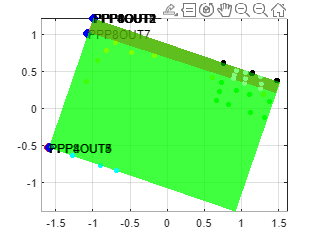


for i =1:8
    idt = [(i-1)*3+1:i*3,(i-1)*3+1];
    PointTri = TrianglePoints4(:,idt);
    fill3(PointTri(1,:),PointTri(2,:),PointTri(3,:),'green',FaceAlpha=0.5,EdgeColor='none');
end


PPP4OUT = TrianglePoints4(:,[1,2,3,6,9,12,15,18]);
scatter3(PPP4OUT(1,1),PPP4OUT(2,1),PPP4OUT(3,1),50,'filled','r')
text(PPP4OUT(1,1),PPP4OUT(2,1),PPP4OUT(3,1)+0.2,['PPP4OUT',num2str(1)])
scatter3(PPP4OUT(1,2),PPP4OUT(2,2),PPP4OUT(3,2),50,'filled','r')
text(PPP4OUT(1,2),PPP4OUT(2,2),PPP4OUT(3,2)+0.2,['PPP4OUT',num2str(2)])
scatter3(PPP4OUT(1,5),PPP4OUT(2,5),PPP4OUT(3,5),50,'filled','r')
text(PPP4OUT(1,5),PPP4OUT(2,5),PPP4OUT(3,5)+0.2,['PPP4OUT',num2str(5)])
scatter3(PPP4OUT(1,7),PPP4OUT(2,7),PPP4OUT(3,7),50,'filled','r')
text(PPP4OUT(1,7),PPP4OUT(2,7),PPP4OUT(3,7)+0.2,['PPP4OUT',num2str(7)])


PPP8OUT = TrianglePoints8(:,[1;8;14;20;26;32;38;2;3;9;18;24;30;36;42;6]);
scatter3(PPP8OUT(1,1),PPP8OUT(2,1),PPP8OUT(3,1),50,'filled','b')
text(PPP8OUT(1,1),PPP8OUT(2,1),PPP8OUT(3,1),['PPP8OUT',num2str(1)])
scatter3(PPP8OUT(1,2),PPP8OUT(2,2),PPP8OUT(3,2),50,'filled','b')
text(PPP8OUT(1,2),PPP8OUT(2,2),PPP8OUT(3,2),['PPP8OUT',num2str(2)])
scatter3(PPP8OUT(1,3),PPP8OUT(2,3),PPP8OUT(3,3),50,'filled','b')
text(PPP8OUT(1,3),PPP8OUT(2,3),PPP8OUT(3,3),['PPP8OUT',num2str(3)])
scatter3(PPP8OUT(1,4),PPP8OUT(2,4),PPP8OUT(3,4),50,'filled','b')
text(PPP8OUT(1,4),PPP8OUT(2,4),PPP8OUT(3,4),['PPP8OUT',num2str(4)])

scatter3(PPP8OUT(1,5),PPP8OUT(2,5),PPP8OUT(3,5),50,'filled','b')
text(PPP8OUT(1,5),PPP8OUT(2,5),PPP8OUT(3,5),['PPP8OUT',num2str(5)])
scatter3(PPP8OUT(1,6),PPP8OUT(2,6),PPP8OUT(3,6),50,'filled','b')
text(PPP8OUT(1,6),PPP8OUT(2,6),PPP8OUT(3,6),['PPP8OUT',num2str(6)])
scatter3(PPP8OUT(1,7),PPP8OUT(2,7),PPP8OUT(3,7),50,'filled','b')
text(PPP8OUT(1,7),PPP8OUT(2,7),PPP8OUT(3,7),['PPP8OUT',num2str(7)])
scatter3(PPP8OUT(1,8),PPP8OUT(2,8),PPP8OUT(3,8),50,'filled','b')
text(PPP8OUT(1,8),PPP8OUT(2,8),PPP8OUT(3,8),['PPP8OUT',num2str(8)])